### Setup

clear variables 
% Sound driver parameters
Buffersize = 1024;
RecorderChannelMapping = [1 2 3 4 5 6];

% Struct for often used constants
Constants = struct( ...
    'Samplerate', 48000, ...
    'AmountOfMicrophones', length(RecorderChannelMapping), ...
    'UCARadius', 0.40 / 2, ...
    'SpeedOfSound', 343, ...
    'SoundOutputOffset', 0.116 / 2, ... % From Genelec 8010A datasheet (half depth)
    'AlphaOffset', 30, ... % Offset betweeen x-axis and mic 1 in degrees
    'AmountOfTaus', 301, ...
    'AmountOfPhis', 360, ...
    'AmountOfOmegas', 601 ...
    );


% Distance parameters
OffsetMin = (2518 - 0.15 / Constants.SpeedOfSound * Constants.Samplerate) / Constants.Samplerate * Constants.SpeedOfSound;
OffsetMax = (2534 - 0.25 / Constants.SpeedOfSound * Constants.Samplerate) / Constants.Samplerate * Constants.SpeedOfSound;
MinDistance = 0.5;
MaxDistance = 2;

% Execution paths
LiveRecording =false;
Synthesized = true;

Debugging = false;
Continuously = false;

### Loading sound

% Define the sound we want to play
if Synthesized
    load("synthesized_signals.mat")
    ProbeSound = signals.clean;
    Constants.SignalLength = length(ProbeSound);
    Constants.AmountOfMicrophones = 3;
    Constants.AlphaOffset = 60;
    Constants.Samplerate = 24000;
else
    t = 0:1/Constants.Samplerate:0.5;
    ProbeSound = transpose(chirp(t, 50, t(end), 1000, "linear"));

    % Since the sound we wish to play is larger than than buffersize. We need to
    % partition the sound that is going to be played, such that it fits with the
    % buffersize. We choose to pad the sound with silence, such that it fits
    ElementsToAdd = (Buffersize - mod(length(ProbeSound), Buffersize));
    ProbeSound = padarray(ProbeSound, ElementsToAdd, 'post');
    
    % Adding silent frames to the end of the probe sound and scaling it
    SilentFramesToAdd = 24;
    Amplitude = 1.22;
    ProbeSound = padarray(ProbeSound, Buffersize*SilentFramesToAdd, 'post');
    ProbeSound = ProbeSound * Amplitude;
    
    Constants.SignalLength = length(ProbeSound);
    
    % Reshape the sounds to fit with the buffersize
    SoundPartitions = reshape(ProbeSound, Buffersize, []);
end

### Precalculations

PreCalcStart = tic;
% Calculate angular position of microphones
Constants.Betas = UCAangles(Constants.AmountOfMicrophones, Constants.AlphaOffset);

% Define linspaces for Phis, Taus, Omegas
Phis = linspace(0, deg2rad(359), Constants.AmountOfPhis); % In rad
Taus = linspace(MinDistance, MaxDistance, Constants.AmountOfTaus) * 2 / Constants.SpeedOfSound * Constants.Samplerate; % In samples
Omegas = round(linspace(0, 12000, Constants.AmountOfOmegas)) + 1; % In Hz
OmegasAngular = Omegas * 2 * pi / 4%/ Constants.Samplerate; % In rad/sample

OmegasAngular = 	1.0e+04 *

    0.0006    0.0132    0.0258    0.0383    0.0509    0.0635    0.0760    0.0886    0.1012    0.1137    0.1263    0.1389    0.1514    0.1640    0.1766    0.1891    0.2017    0.2143    0.2268    0.2394    0.2520    0.2645    0.2771    0.2897    0.3022    0.3148    0.3274    0.3399    0.3525    0.3651    0.3776    0.3902    0.4028    0.4153    0.4279    0.4405    0.4530    0.4656    0.4782    0.4907    0.5033    0.5158    0.5284    0.5410    0.5535    0.5661    0.5787    0.5912    0.6038    0.6164


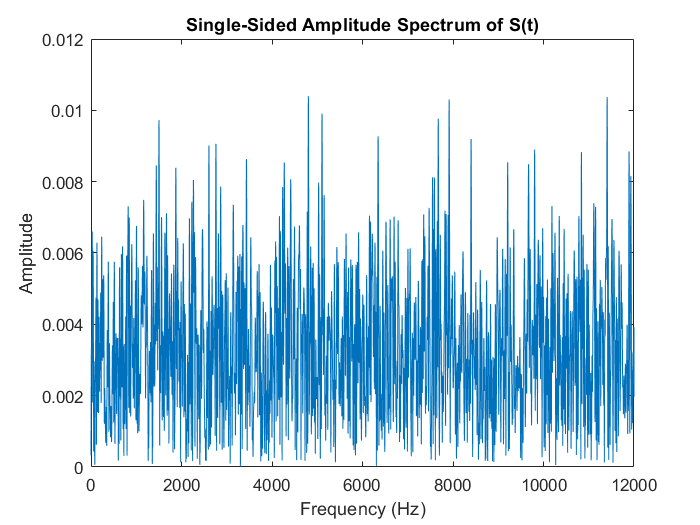


% Find the one sided FFT of the received sound
nFFT = 2^nextpow2(length(ProbeSound));
ProbeFFT = OneSidedFFT(ProbeSound, ...
    "Plot", true, "Samplerate", Constants.Samplerate);

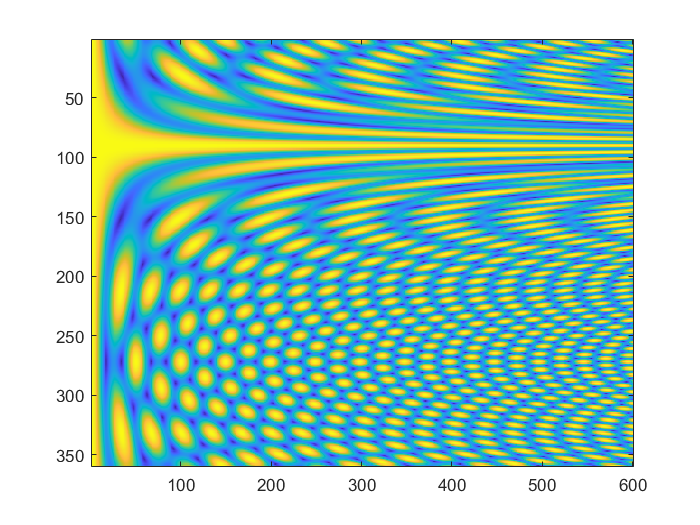

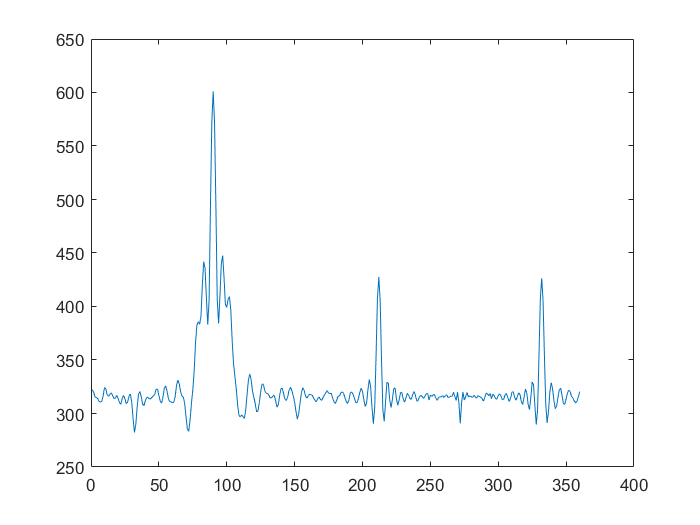


% Define linspaces for indexing Omegas
OmegasBinIndices = linspace(0, Constants.AmountOfOmegas-1, Constants.AmountOfOmegas);
OmegasFFTIndices = round(Omegas * Constants.SignalLength / Constants.Samplerate);


% Find the beamformer weights
wDS = BeamformerDS(Phis, OmegasAngular, Constants); % <-- Her burde vi nok bare udregne alle steering vectors, således vi bare kan bruge dem senere til udregningen af Yk og vores beamformer

wDSHermitian = pagectranspose(wDS); % Hermitian transpose of wDS

% Calculate Zbar
Zbar = CalculateZbar(ProbeFFT(OmegasFFTIndices), Phis, Taus, OmegasBinIndices, Constants);

toc(PreCalcStart)

Elapsed time is 10.078432 seconds.


%clear OmegasBinIndices ProbeFFT 

### Sound driver

if LiveRecording
    SoundDriver = audioPlayerRecorder( ...
        "SampleRate", Constants.Samplerate, ...
        "Device", "ZOOM Audio IF with Rec ASIO", ... % You must choose your own device
        'SupportVariableSize', true, ...
        "BufferSize", Buffersize, ...
        "RecorderChannelMapping", RecorderChannelMapping, ...
        "BitDepth", '32-bit float' ...  
        );
    
    if Debugging
        InputScope = timescope( ...
            'Name', 'Input', ...
            'SampleRate', Constants.Samplerate, ...
            'BufferLength', Buffersize, ...
            'AxesScaling', "auto", ...
            'TimeSpanSource', "property", ... 
            'TimeSpan', 5 ...
            );
        
        OutputScope = timescope( ...
            'Name', 'Output', ...
            'SampleRate', Constants.Samplerate, ...
            'BufferLength', Buffersize, ...
            'AxesScaling', "auto", ...
            'TimeSpanSource', "property", ... 
            'TimeSpan', 5 ...
            );
        
        InputScope.show;
        OutputScope.show;
    end
end

### Echolocation

while true
    EchoStart = tic;
    if Synthesized
        ReceivedSound = signals.reflec;
    elseif LiveRecording
        % Play the sound and store the recorded data into ReceivedSound
        ReceivedSound = PlayAndRecordSound(SoundDriver, SoundPartitions, Constants.AmountOfMicrophones);
        %ReceivedSound = RemoveDelay(ReceivedSound, Constants);
    else
        ReceivedSound = struct2array(load('Recordings\1.2Meter30Degree.mat'));
        %ReceivedSound = RemoveDelay(ReceivedSound, Constants);
    end
    
    % Find the one sided FFT of the received sound
    ReceivedFFT = transpose(OneSidedFFT(ReceivedSound));
    
    %Plots for debugging
    for i = 1: Constants.AmountOfMicrophones
        figure
        plot(ReceivedSound(:, i))
        title("Mic" + i + ": Time domain")
        figure
        plot(abs(ReceivedFFT(i, :)))
        title("Mic" + i + ": Frequency domain, All frequencies")
        figure
        plot(abs(ReceivedFFT(i, OmegasFFTIndices)))
        title("Mic" + i + ": Frequency domain, Specified frequencies")
    end
    
    % Calculate Ybar
    Ybar = CalculateYbar(ReceivedFFT, OmegasFFTIndices, wDSHermitian, Constants, ...
       "Plot", true);
    
    % Find the cost matrix
    CostMatrix = CostFunction(Ybar, Zbar, Constants, ...
        "Plot", true);
    
    % Determine the angle and distance from the cost matrix
    [Angle, Distance] = Estimator(Phis, Taus, CostMatrix, Constants)

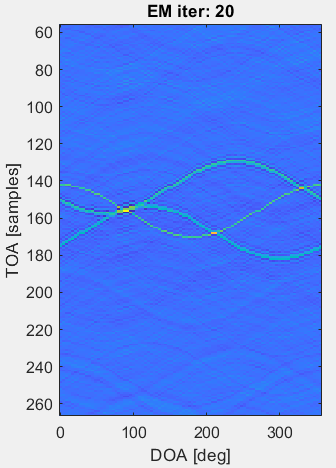 Distance: 1.11, DOA: 90

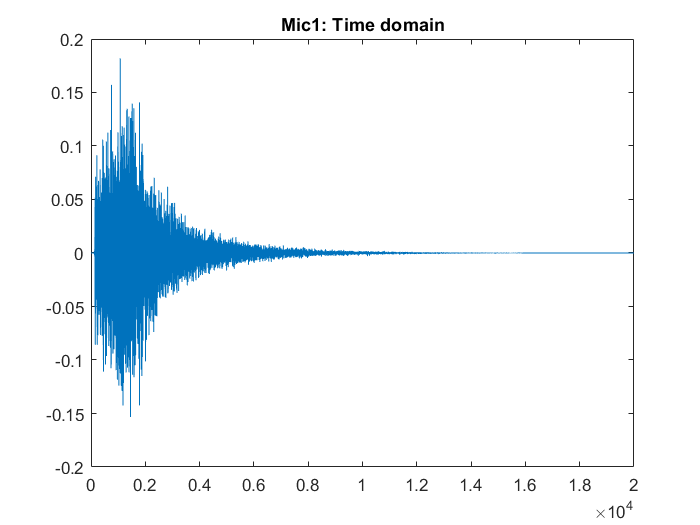

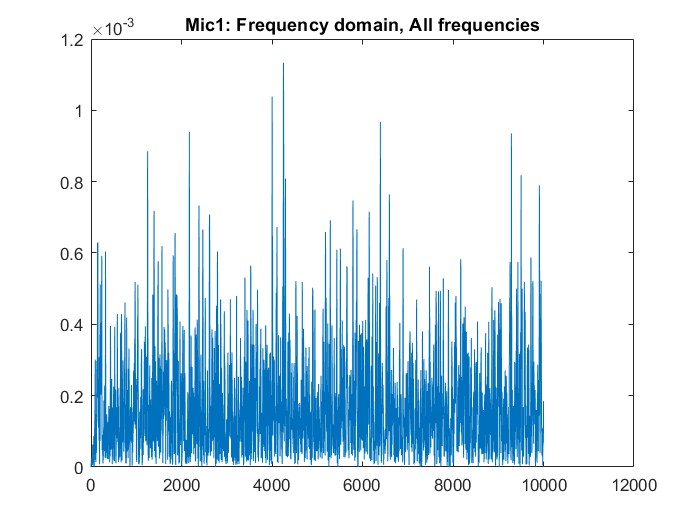

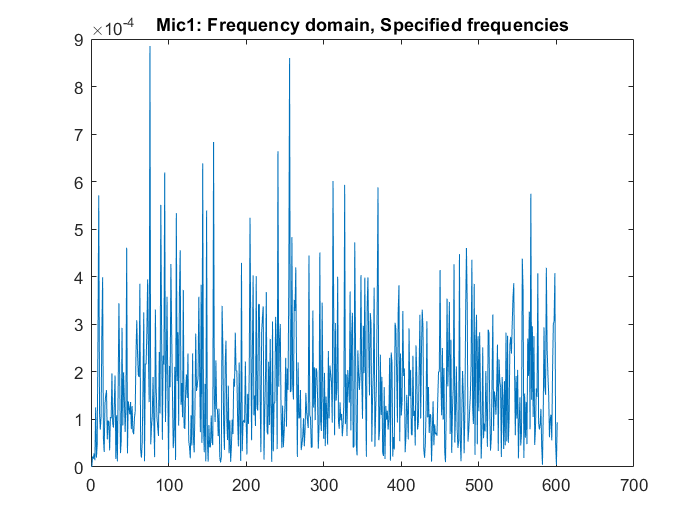

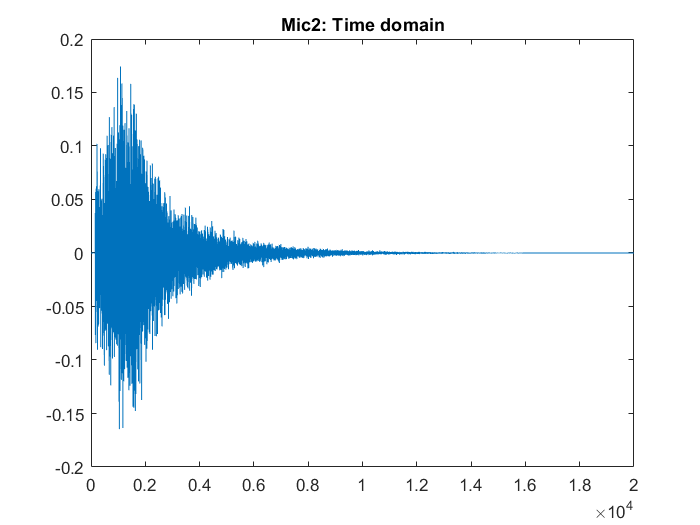

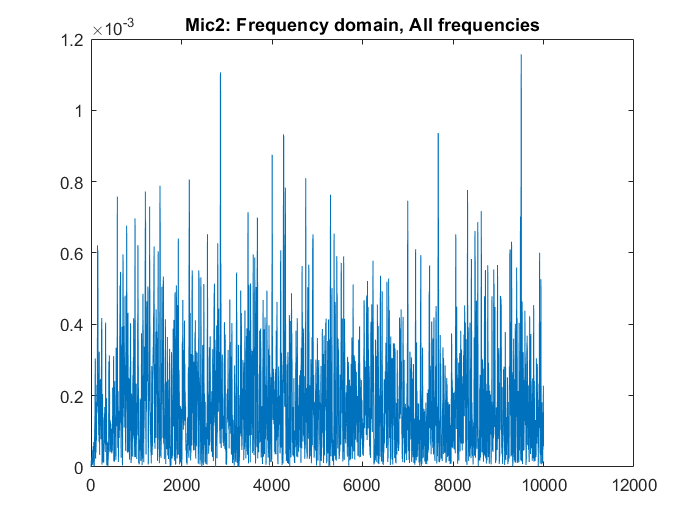

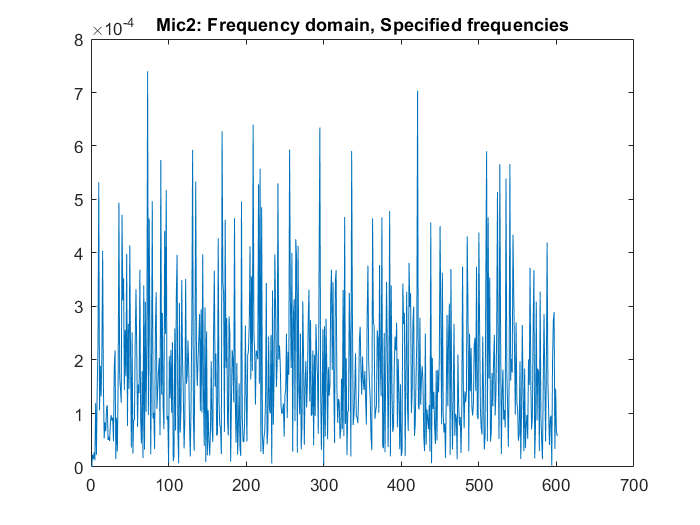

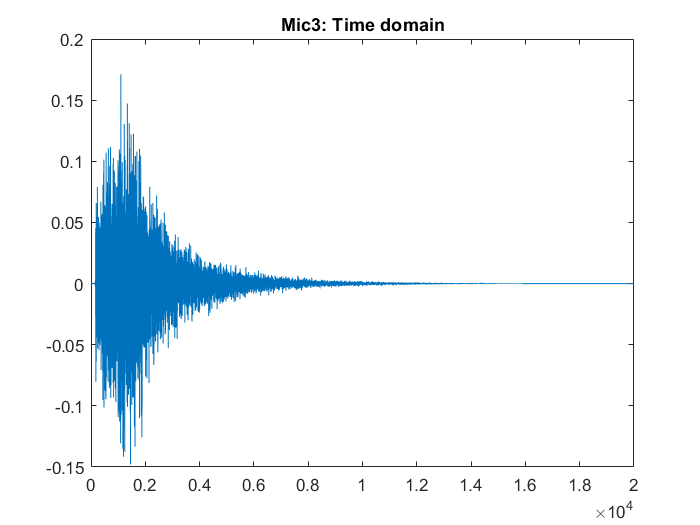

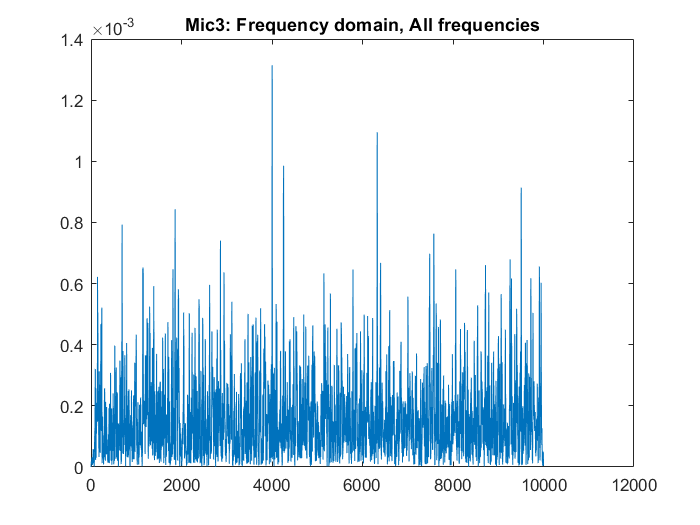

Angle = 89.0000

Distance = 1.1150

Elapsed time is 2.531463 seconds.


    
    toc(EchoStart)
    
    if ~Continuously 
        break;
    end
end

SaveSound = ReceivedSound;